% Initialize the environment (if required)
mystartdefaults

% Constants and parameters
recipunit = 1.0E+10;
hbar = 1.0545718e-34; % Planck's constant over 2pi
elm = 9.10938356e-31; % Electron mass
qel = 1.602176634e-19; % Elementary charge
tol = 1e-12;
ekinscale = ((hbar*recipunit)^2/(2*elm))/qel;
step_size = 0.5; % in Ångstroms

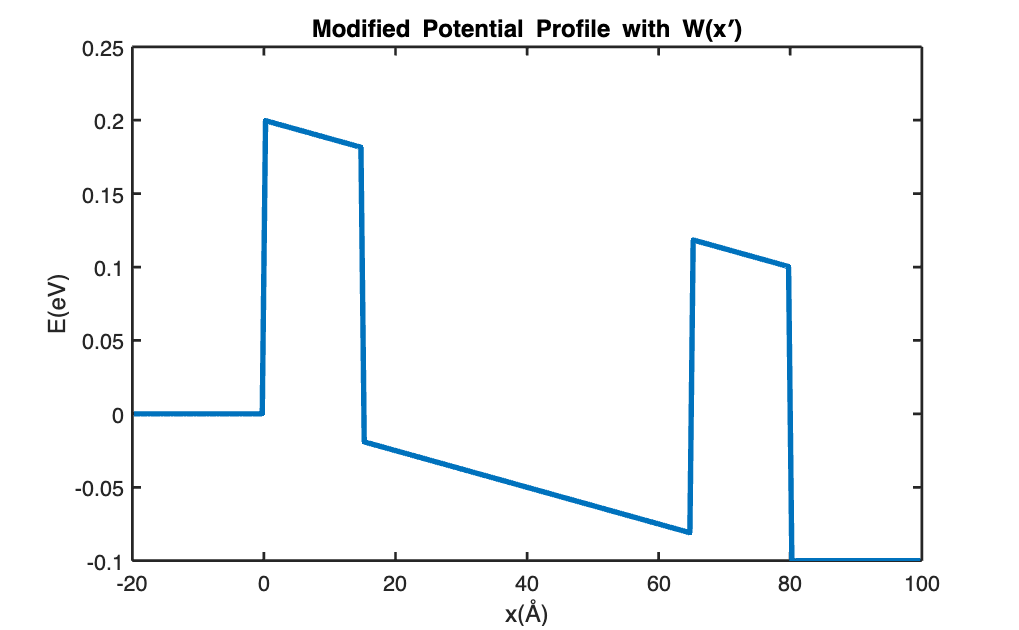

% Parameters for the step function potential
x_min = -20; % Minimum x in Angstroms
x_max = 100; % Maximum x in Angstroms
U0 = 0; % Potential for x < 0
U1 = -0.1; % Step potential in eV

% Discretize the space
n = (x_max - x_min)/step_size;
% Define the initial step function potential
U = zeros(n, 1); % Initialize potential array
% Define the region where the electric field is applied
x_prime_min = 0; % Starting point of the heterostructure in Angstroms
x_prime_max = 80; % Ending point of the heterostructure in Angstroms

% Modify the potential profile to include the electric field effect
W = zeros(n, 1); % Initialize modified potential array
U = zeros(n, 1); % Potential barrier
x = zeros(n, 1);

for i = 1:n
    x(i) = x_min + step_size/2 + (i - 1) * step_size;
    if x(i) <= 15 && x(i) > 0
        U(i) = 0.2;
    elseif x(i) >= 65 && x(i) <= 80
        U(i) = 0.2;
    elseif x(i) >= 80
        U(i) = -0.1;
    else
        U(i) = 0;
    end
end
%plot(x, U, 'LineWidth', 2);
%ylim([-0.1 0.25]);
%plot(x, V, 'LineWidth', 2);
% Calculate the magnitude of the electric field
E = - U1 / (x_prime_max - x_prime_min);

for i = 1:n
    if x(i) > x_prime_min && x(i) < x_prime_max
        W(i) = U(i) - E * x(i);
    elseif x(i) >= x_prime_max
        W(i) = -0.1;
    else
        W(i) = 0;
    end
end

% Plot the modified potential profile
figure;
plot(x, W, 'LineWidth', 3);
title('Modified Potential Profile with W(x\prime)');
xlabel('x(Å)');
ylabel('E(eV)');
ylim([-0.1 0.25]);
saveas(gcf, 'biased_junction.png');  % You can specify other file formats like '.jpg', '.pdf', etc.